clc
clear global
data=load('infla.txt')

data =         3741
        3608
        3735
        3695
        3810
        3819
        3291
        3053
        3908
        4035


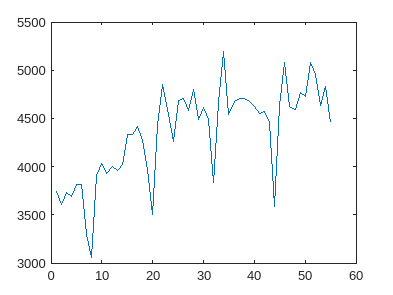

% Create a plot of the data
plot(data);

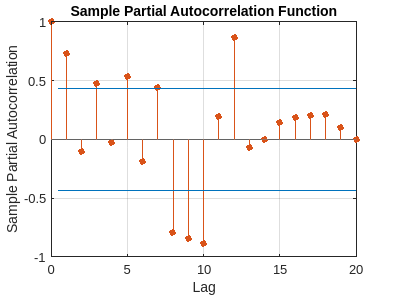

auto_correlation=autocorr(data);
parcorr(auto_correlation)

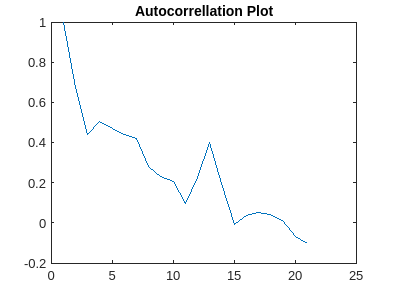

plot(auto_correlation)
title('Autocorrellation Plot');

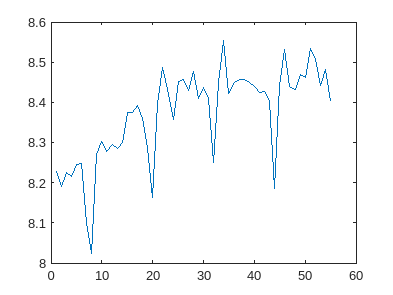

stable=log(data);
plot(stable);

%first differenciation
% D1=LagOp({1,-1},'Lags',[0,1]);
% dY=filter(D1,data);
%second differenciation
% D2=D1*D1;
% dY=filter(D2,data);
%enlever la saisonnalite
% D2=LagOp({1,-1},'Lags',[0,12]);
% ddY=filter(D2,data)
%pour enlever la saisonnalite et la tendance
% D11= LagOp({1,-1},'Lags',[0,1])
% D112= LagOp({1,-1},'Lags',[0,12])
% D12= D11*D112;
% dddY=filter(D12,data)
%modelisation
model1 =arima('Constant',0,'ARLags',1,'D',1,'MALags',1,'Seasonality',12,'SMALags',1);
fit1 = estimate(model1,data);

 
    ARIMA(1,1,1) Model Seasonally Integrated with Seasonal MA(1) (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue  
                ________    _____________    __________    __________

    Constant           0             0             NaN            NaN
    AR{1}       -0.20603       0.26083        -0.78988         0.4296
    MA{1}       -0.27072       0.10961         -2.4699       0.013513
    SMA{1}      -0.27072       0.10952          -2.472       0.013437
    Variance       28595        5055.3          5.6565     1.5451e-08



e1=infer(fit1,data)

e1 =    -0.0000
    0.0000
   -0.0000
    0.0000
   -0.0001
    0.0005
   -0.0027
    0.0129
   -0.0628
    0.3049


MAPE1=(100/N)*sum(abs( e1./data))

MAPE1 = 2.6094

% autocorr(e1)
model2 =arima('Constant',0,'ARLags',1,'D',1,'MALags',1,'SARLags',1,'Seasonality',12);
fit2 = estimate(model2,data);

 
    ARIMA(1,1,1) Model Seasonally Integrated with Seasonal AR(1) (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue  
                ________    _____________    __________    __________

    Constant           0             0            NaN             NaN
    AR{1}       -0.17711       0.11893        -1.4892         0.13644
    SAR{1}      -0.17711       0.11903         -1.488         0.13676
    MA{1}       -0.40496       0.18369        -2.2045        0.027486
    Variance       28428        5006.8         5.6779      1.3637e-08



e2=infer(fit2,data)

e2 =    -0.0000
    0.0000
   -0.0000
    0.0001
   -0.0003
    0.0017
   -0.0085
    0.0417
   -0.2006
    0.9347


MAPE2=(100/N)*sum(abs( e2./data))

MAPE2 = 2.6145

% autocorr(e2)
model3 =arima('Constant',0,'ARLags',1:2,'D',1,'MALags',1,'Seasonality',12,'SMALags',1);
fit3 = estimate(model3,data);

 
    ARIMA(2,1,1) Model Seasonally Integrated with Seasonal MA(1) (Gaussian Distribution):
 
                  Value      StandardError    TStatistic      PValue  
                _________    _____________    __________    __________

    Constant            0             0            NaN             NaN
    AR{1}        -0.69512         0.311        -2.2351         0.02541
    AR{2}        -0.36471       0.20009        -1.8228        0.068336
    MA{1}       -0.030187       0.16423        -0.1838         0.85417
    SMA{1}      -0.030187       0.16423        -0.1838         0.85417
    Variance        27373        4958.9           5.52      3.3903e-08



e3=infer(fit3,data)

e3 =    -0.0739
   -0.4088
    0.9487
   -0.6888
   -1.2884
    4.3441
   -4.7471
   -2.8635
   18.4736
  -27.3581


MAPE3=(100/N)*sum(abs( e3./data))

MAPE3 = 2.6941

% autocorr(e3)
model4 =arima('Constant',0,'ARLags',1:2,'D',1,'MALags',1,'SARLags',1,'Seasonality',12);
fit4 = estimate(model4,data);

 
    ARIMA(2,1,1) Model Seasonally Integrated with Seasonal AR(1) (Gaussian Distribution):
 
                  Value      StandardError    TStatistic      PValue  
                _________    _____________    __________    __________

    Constant            0             0             NaN            NaN
    AR{1}        -0.67274       0.37097         -1.8135        0.06976
    AR{2}        -0.35391       0.22094         -1.6019        0.10919
    SAR{1}      -0.038227       0.70933       -0.053893        0.95702
    MA{1}       -0.048229       0.60387       -0.079867        0.93634
    Variance        27368        4965.1          5.5119     3.5489e-08



e4=infer(fit4,data)

e4 =    -0.0986
   -0.3184
    0.8594
   -0.7350
   -1.0311
    4.0368
   -4.7600
   -2.3579
   17.9317
  -27.4235


MAPE4=(100/N)*sum(abs( e4./data))

MAPE4 = 2.6888

% autocorr(e3)
MAPES=[MAPE1 MAPE2 MAPE3 MAPE4];
fits=[fit1 fit2 fit3 fit4]

fits =   1×4 arima array with properties:

    P
    Q
    Description
    Distribution
    Constant
    AR
    SAR
    MA
    SMA
    D
    Seasonality
    Beta
    Variance


best_model=fits(1)

best_model =   arima with properties:

     Description: "ARIMA(1,1,1) Model Seasonally Integrated with Seasonal MA(1) (Gaussian Distribution)"
    Distribution: Name = "Gaussian"
               P: 14
               D: 1
               Q: 2
        Constant: 0
              AR: {-0.206027} at lag [1]
             SAR: {}
              MA: {-0.270723} at lag [1]
             SMA: {-0.270723} at lag [1]
     Seasonality: 12
            Beta: [1×0]
        Variance: 28595.1

% model_names=["model1" "model2"  "model3"  "model4"];
best_mape=MAPES(1)

best_mape = 2.6094

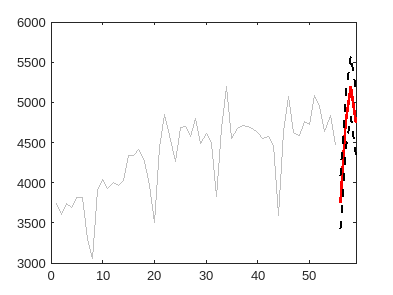

for i=2:length(MAPES)
    if MAPES(i) < best_mape
        best_mape=MAPES(i)
        best_model=fits(i)
        % best_model=model_names(i)
    end
end
%plot the best model
[Yf,YMSE] = forecast(best_model,4,'Y0',data);
upper = Yf + 1.96*sqrt(YMSE); 
lower = Yf - 1.96*sqrt(YMSE);
 
figure(9)
plot(data,'Color',[.75,.75,.75])
hold on
h1 = plot(N+1:N+4,Yf,'r','LineWidth',2);
h2 = plot(N+1:N+4,upper,'k--','LineWidth',1.5);
plot(N+1:N+4,lower,'k--','LineWidth',1.5)
xlim([0,N+4])

hold off